# **Equilibrium point / Transfer function (p1)**

## **Defining Variables**

clear; clc; close all;

syms G X I U D
Gb = 4.5;
Ib = 15;
P1 = 0;
P2 = 0.025;
P3 = 0.000013;
V = 12;
n = 5.54/60;
F = [ -P1*G-X*(G+Gb)+D;
      -P2*X+P3*I;
      -n*(I+Ib)+U/V ];
y = G;

St = [G;X;I];
In = [U;D];

## **Equilibrium State**

St_e = [0;0;0];
In_e = [n*Ib*V;0];
Fe = subs(subs(F,In,In_e),St,St_e);

## Linearize

% f(x) = f(xe,ue) + (grad(f,x)|x=xe,u=ue)*(x-xe) + (grad(f,u)|x=xe,u=ue)*(u-ue)
grad_F_St = [ diff(F(1),St(1)), diff(F(1),St(2)), diff(F(1),St(3));
              diff(F(2),St(1)), diff(F(2),St(2)), diff(F(2),St(3));
              diff(F(3),St(1)), diff(F(3),St(2)), diff(F(3),St(3)) ];
grad_F_In = [ diff(F,In(1)) , diff(F,In(2)) ];
A = double(subs(subs(grad_F_St,In,In_e),St,St_e))

A =          0   -4.5000         0
         0   -0.0250    0.0000
         0         0   -0.0923


B = double(subs(subs(grad_F_In,In,In_e),St,St_e));
B = B(:,1)

B =          0
         0
    0.0833


C = [1,0,0]

C =      1     0     0


D = 0

D = 0

## Transfer Function

syms s
n = size(A,1);
Gp = C*inv(s*eye(n)-A)*B;
ExpFun = matlabFunction(simplifyFraction(Gp,'Expand',true));
ExpFun = str2func(regexprep(func2str(ExpFun), '\.([/^\\*])', '$1'));
Gp = tf(ExpFun(tf('s')));
for i = 1:length(Gp)
    [num,den] = tfdata(Gp(i));
    Gp(i) = tf(num{1}/den{1}(1),den{1}/den{1}(1));
end
Gp = Gp(1)


Gp =
 
           -4.875e-06
  -----------------------------
  s^3 + 0.1173 s^2 + 0.002308 s
 
Continuous-time transfer function.



[Gp_Num, Gp_Den] = tfdata(Gp);

# **Analog Control (p2)**

Gc = pidtune(Gp,'PID')


Gc =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = -22.7, Ki = -0.0995, Kd = -1e+03
 
Continuous-time PID controller in parallel form.



trans_info = stepinfo(feedback(series(Gc,Gp),1))

trans_info = struct with fields:
        RiseTime: 29.3956
    SettlingTime: 405.7572
     SettlingMin: 0.9186
     SettlingMax: 1.0793
       Overshoot: 7.9320
      Undershoot: 0
            Peak: 1.0793
        PeakTime: 66.0147


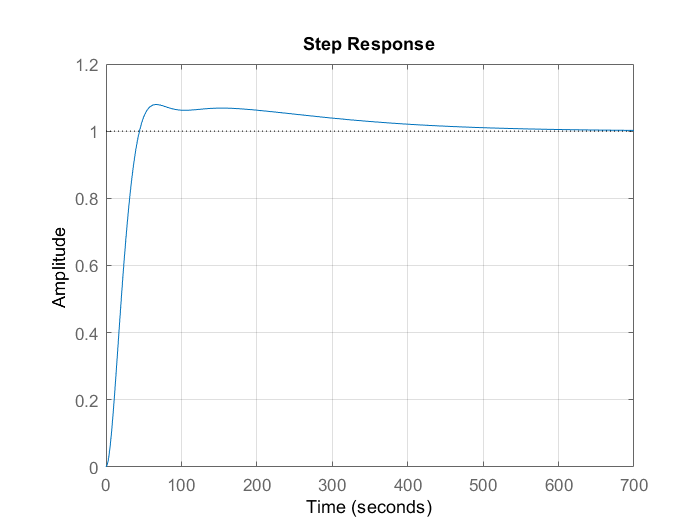

step(feedback(series(Gc,Gp),1))
grid on

# **Digital Control (P3)**

% 2 < tr/Ts < 10
Ts = round(trans_info.RiseTime/8)

Ts = 4

Gd_1 = c2d(Gc,Ts,'tastin')


Gd_1 =
 
            Ts*(z+1)        2*(z-1) 
  Kp + Ki * -------- + Kd * --------
            2*(z-1)         Ts*(z+1)

  with Kp = -22.7, Ki = -0.0995, Kd = -1e+03, Ts = 4
 
Sample time: 4 seconds
Discrete-time PID controller in parallel form.



Gd_2 = c2d(Gc,Ts,'matched')


Gd_2 =
 
              Ts            z-1 
  Kp + Ki * ------ + Kd * ------
              z-1           Ts  

  with Kp = -23.1, Ki = -0.0994, Kd = -1.05e+03, Ts = 4
 
Sample time: 4 seconds
Discrete-time PID controller in parallel form.



# **Discrete Transfer Function (p4)**

**Using Theoretical Calculations :**


$$\begin{array}{l}
\mathrm{Using}\;\mathrm{Mathematica}\\
\mathrm{Simplify}\left\lbrack \mathrm{InverseLaplaceTransform}\left\lbrack -4.875*10ˆ-6/\left(sˆ2*\left(sˆ2+0.1173*s+0.002308\right)\right),s,t\right\rbrack //N\right\rbrack \\
-0.00211t+0.0085e^{-0.0923\,t} -0.115856e^{-0.025\,t} +0.1073
\end{array}$$



$$\mathrm{Simplify}\left\lbrack \left(1-zˆ-1\right)*\left(0.10735/\left(1-zˆ-1\right)-0.0021122*z/\left(z-1\right)ˆ2+0.00850593/\left(1-\mathrm{Exp}\left\lbrack -0.0923*4\right\rbrack *zˆ-1\right)-0.115856/\left(1-\mathrm{Exp}\left\lbrack -0.025*4\right\rbrack *zˆ-1\right)\right)\right\rbrack$$



$$-7*{10}^{-8\;} \frac{z^3 +705.031+2280.422z+559.37687}{\left(z-1.\right)\,\left(z-0.904837\right)\,\left(z-0.691287\right)}$$


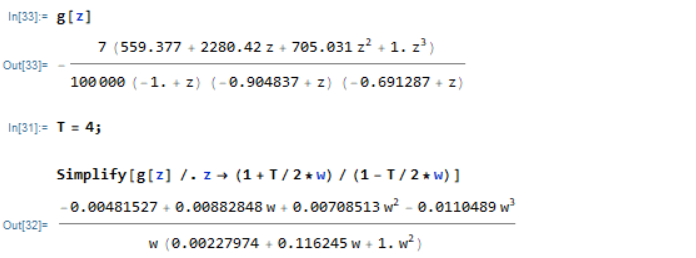

**Using c2d in matlab :**

Gp_d = c2d(Gp,Ts,'zoh')


Gp_d =
 
  -4.635e-05 z^2 - 0.0001652 z - 3.666e-05
  ----------------------------------------
     z^3 - 2.596 z^2 + 2.221 z - 0.6254
 
Sample time: 4 seconds
Discrete-time transfer function.



## Root Locus

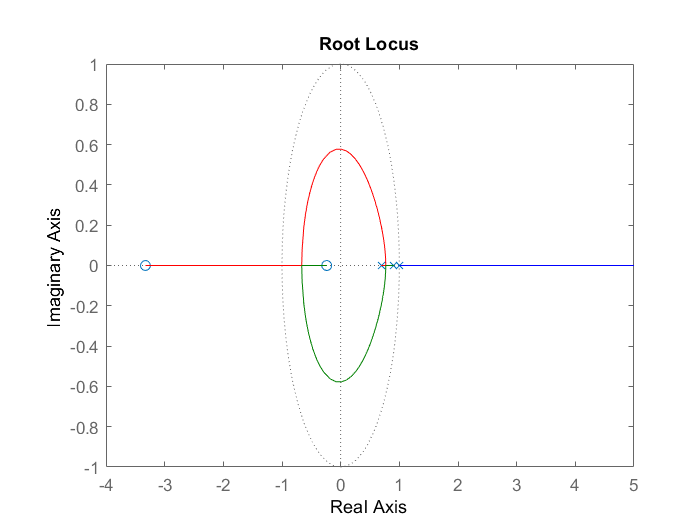

rlocus(Gp_d)

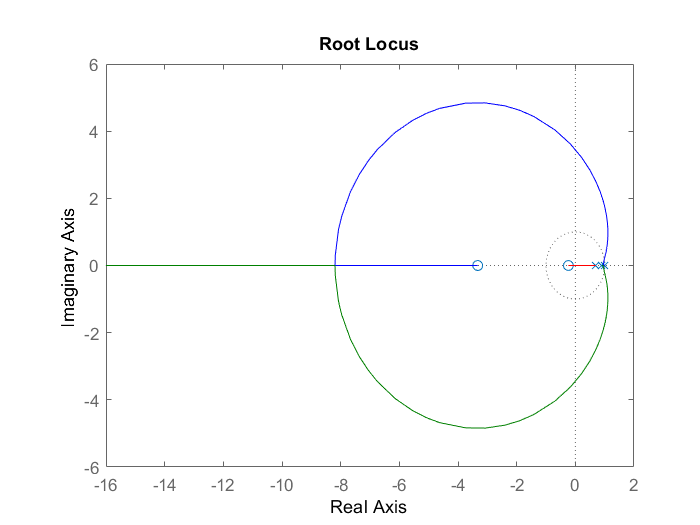

rlocus(-Gp_d)

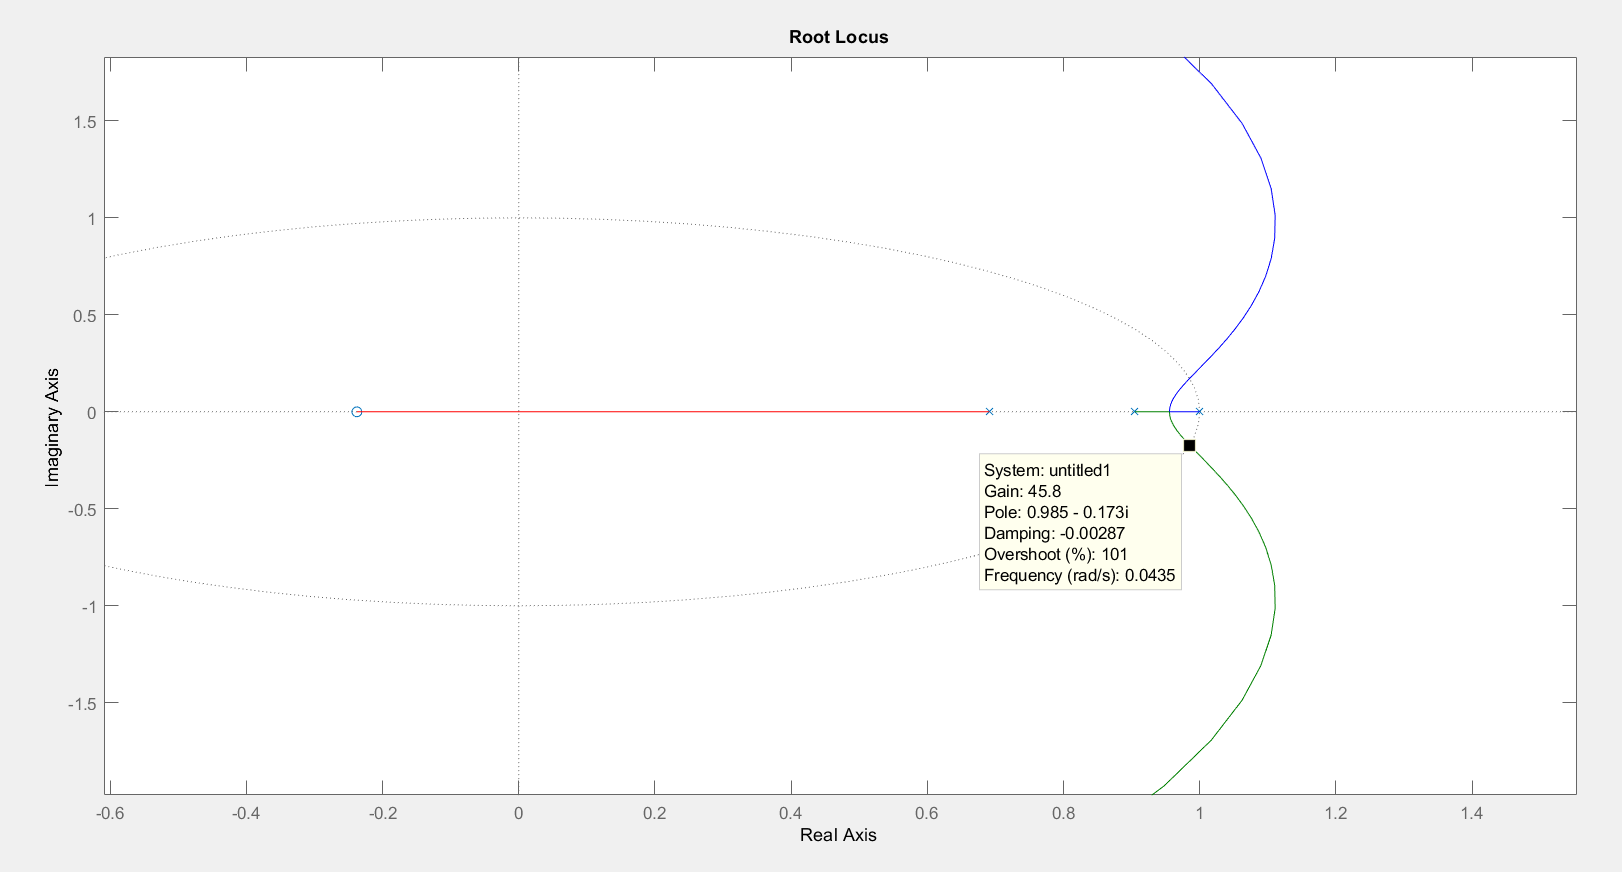

`Therefore => -45.8<k<0`

## `Bode plot (Z domain)`

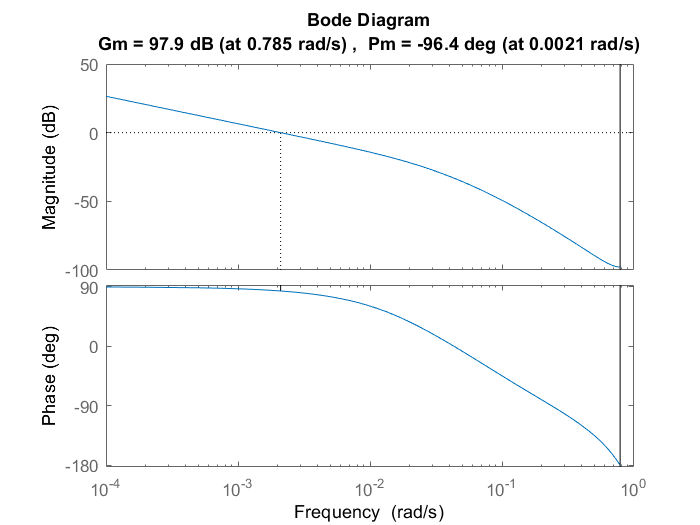

margin(Gp_d)

[Gm,Pm,Wgm,Wpm] = margin(Gp_d)

Gm = 7.8339e+04

Pm = -96.3569

Wgm = 0.7854

Wpm = 0.0021

## **Bode plot (Frequency domian)**

Using Mathematica :


$$G\left\lbrack \mathrm{w_}\right\rbrack :=\left(-4.635*10ˆ-5*zˆ2-0.0001652*zˆ1-3.666*10ˆ-5\right)/\left(zˆ3-2.596*zˆ2+2.221*z-0.6254\right)/\ldotp z\to \;\left(\left(T/2*w+1\right)/\left(1-T/2*w\right)\right)$$


= $\frac{0.0000048159-0.0000088798w-0.000007883w^2 +0.00001276w^3 }{0.0000077611-0.002297281w-0.116323w^2 -1.w^3 }$

num = [0.00001276 , -0.000007883 , -0.0000088798 , 0.0000048159];
den = [-1 , -0.116323 , -0.00229728 , 0.0000077611];
gw = tf(num,den)


gw =
 
  -1.276e-05 s^3 + 7.883e-06 s^2 + 8.88e-06 s - 4.816e-06
  -------------------------------------------------------
         s^3 + 0.1163 s^2 + 0.002297 s - 7.761e-06
 
Continuous-time transfer function.



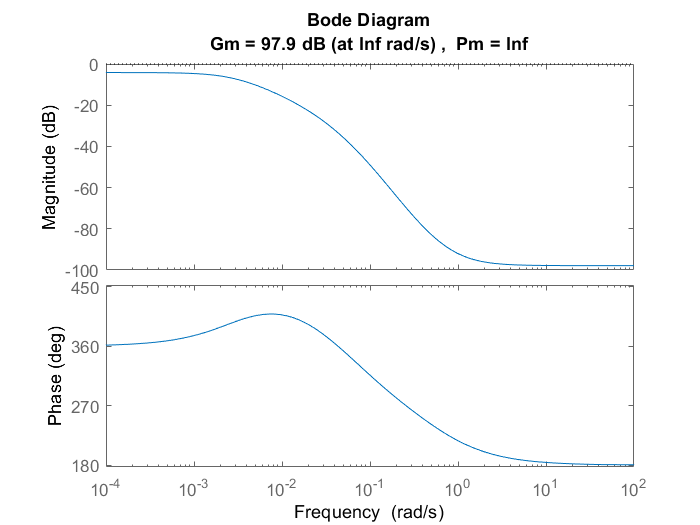

margin(gw)

[Gm,Pm,Wgm,Wpm] = margin(gw)

Gm = 7.8370e+04

Pm = Inf

Wgm = Inf

Wpm = NaN

# **Design a controler (p5)**

Ts = 10;
Gp


Gp =
 
           -4.875e-06
  -----------------------------
  s^3 + 0.1173 s^2 + 0.002308 s
 
Continuous-time transfer function.



Gp_d = c2d(Gp,Ts,'zoh')


Gp_d =
 
  -0.0006143 z^2 - 0.00186 z - 0.000342
  -------------------------------------
   z^3 - 2.176 z^2 + 1.485 z - 0.3093
 
Sample time: 10 seconds
Discrete-time transfer function.



[num,den]=tfdata(Gp_d);
[z,p,k] = tf2zp(num{1},den{1})

z =    -2.8306
   -0.1967


p =     1.0000
    0.7788
    0.3972


k = -6.1431e-04

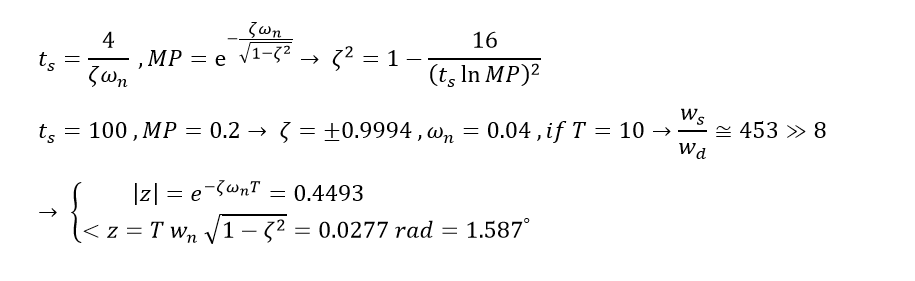

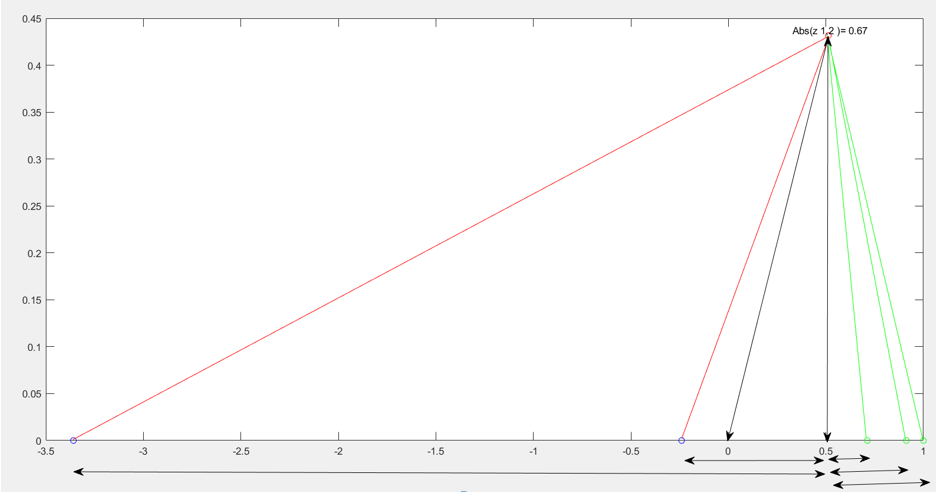

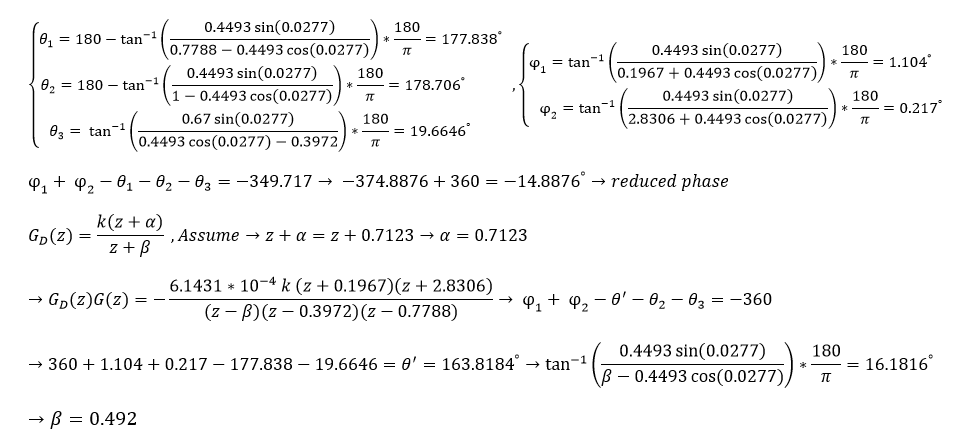

So, Reconstructing the Open loop Transfer function : Gp(z)*G(z) 

GC_pre = tf(-6.1431*10^-4*conv([1 0.1967],[1 2.8306]),conv(conv([1,-0.492],[1,-0.3972]), [1,-0.7788]),Ts)


GC_pre =
 
  -0.0006143 z^2 - 0.00186 z - 0.000342
  -------------------------------------
   z^3 - 1.668 z^2 + 0.8879 z - 0.1522
 
Sample time: 10 seconds
Discrete-time transfer function.



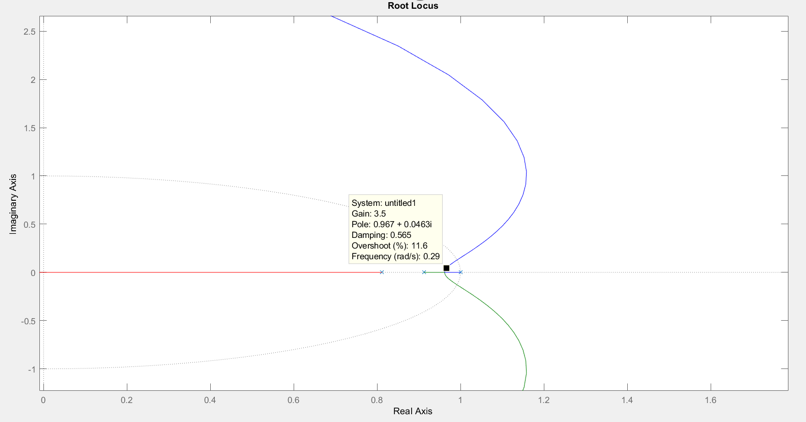

Decide to choose the controller coeffient form root locus

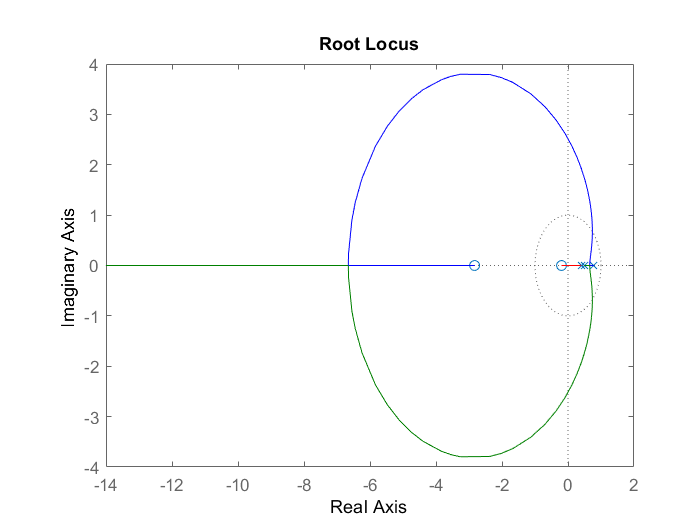

rlocus(-GC_pre)

choosing k = -3.5, then plot the step response 

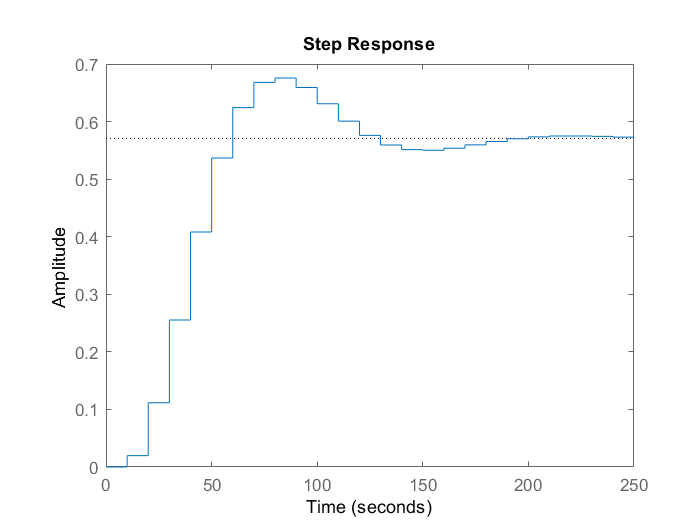

step(feedback(-32*GC_pre,1))

stepinfo(step(feedback(-32*GC_pre,1)))

ans = struct with fields:
        RiseTime: 3.4343
    SettlingTime: 18.5526
     SettlingMin: 0.5367
     SettlingMax: 0.6758
       Overshoot: 17.6908
      Undershoot: 0
            Peak: 0.6758
        PeakTime: 9



GC = -32*GC_pre


GC =
 
   0.01966 z^2 + 0.05951 z + 0.01095
  -----------------------------------
  z^3 - 1.668 z^2 + 0.8879 z - 0.1522
 
Sample time: 10 seconds
Discrete-time transfer function.



# **Comparing the features per plot (p6)**

## Bode plot (Frequency Domain)

 ( Uncontrolled system )

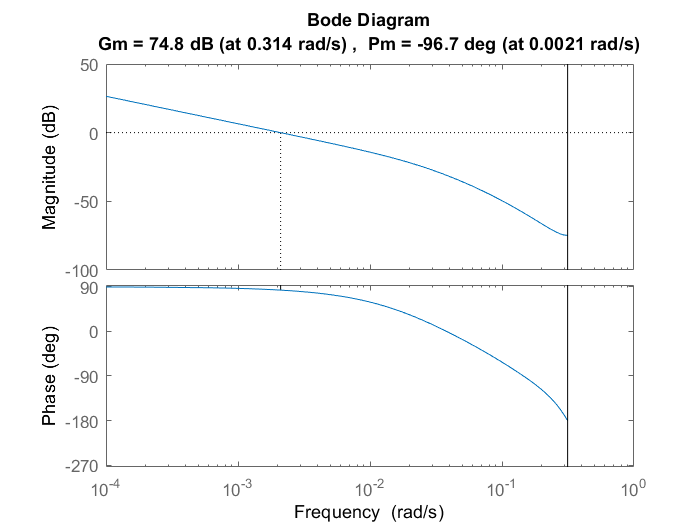

margin(Gp_d)

[Gm,Pm,Wgm,Wpm] = margin(Gp_d)

Gm = 5.5026e+03

Pm = -96.7192

Wgm = 0.3142

Wpm = 0.0021

## Root Locus (Uncontrolled system)

Ts = 0.2;
Gp_d = c2d(Gp,Ts,'zoh')


Gp_d =
 
  -6.462e-09 z^2 - 2.57e-08 z - 6.387e-09
  ---------------------------------------
    z^3 - 2.977 z^2 + 2.954 z - 0.9768
 
Sample time: 0.2 seconds
Discrete-time transfer function.



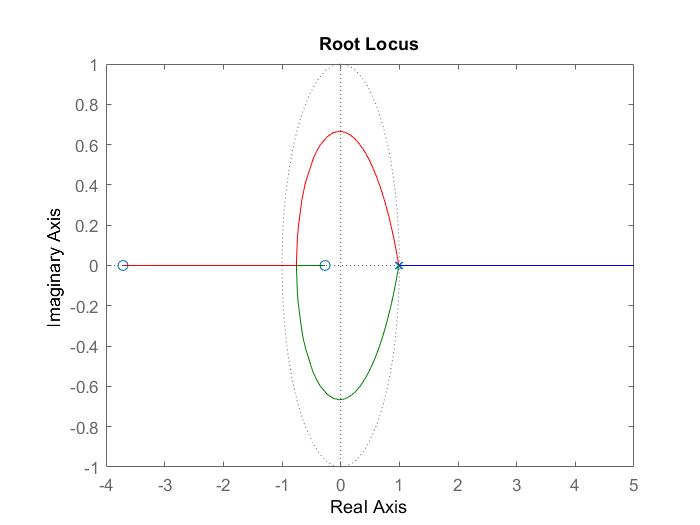

rlocus(Gp_d)

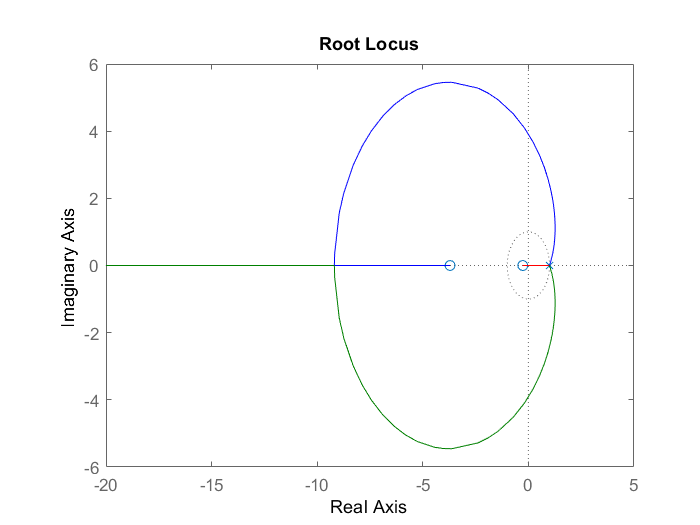

rlocus(-Gp_d)

## 
$$\mathrm{Bode}\;\mathrm{plot}\;\left(\mathrm{Frequency}\;\mathrm{Domain}\right)$$



$$\text{ }\left(\text{Contolled}\text{ }\text{system}\right)\text{}$$


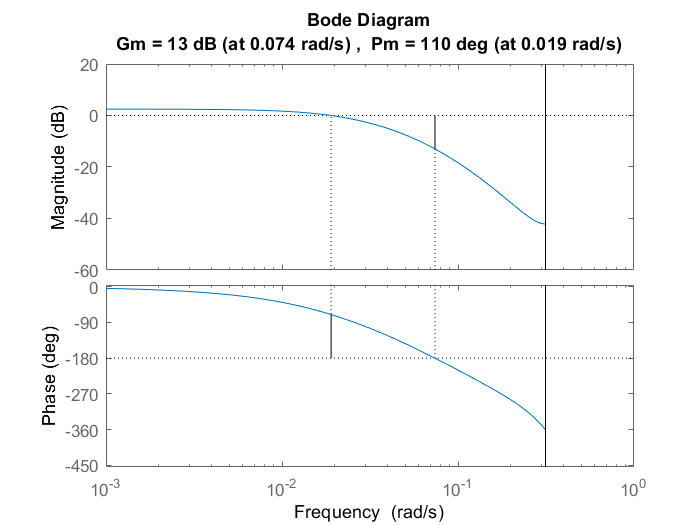

margin(GC)

[Gm,Pm,Wgm,Wpm] = margin(GC)

Gm = 4.4548

Pm = 110.0369

Wgm = 0.0740

Wpm = 0.0190

## Root Locus (Controlled system)

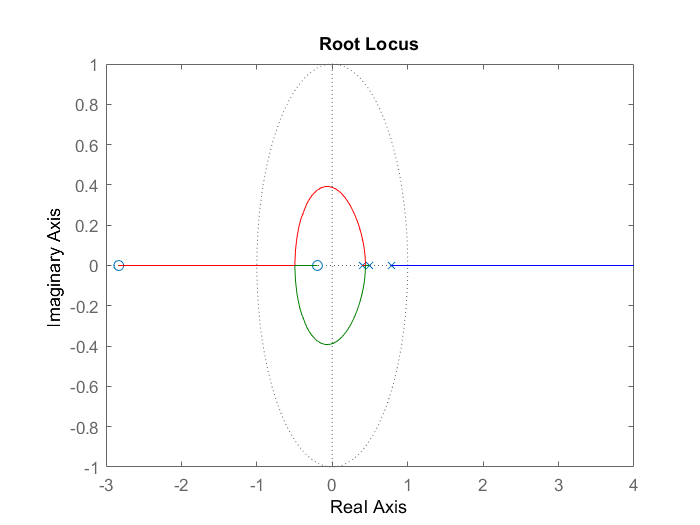

rlocus(-GC)

# **DeadBeat controller (p7)**

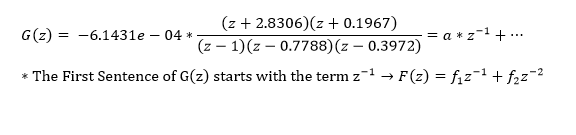

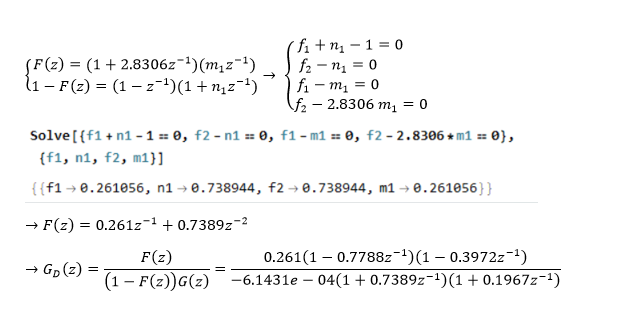

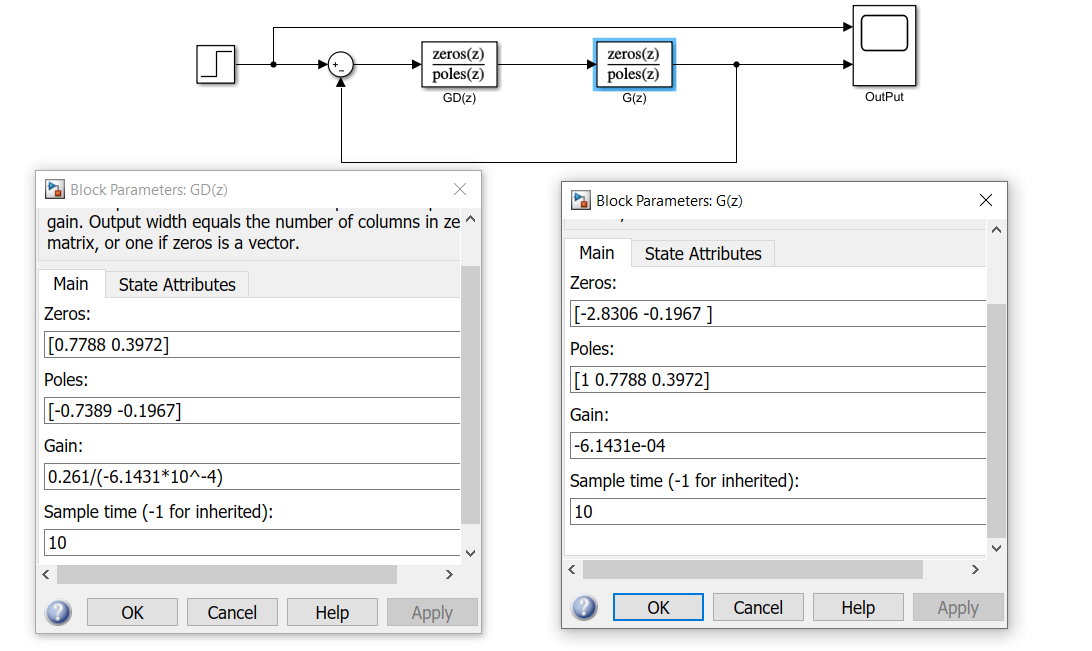

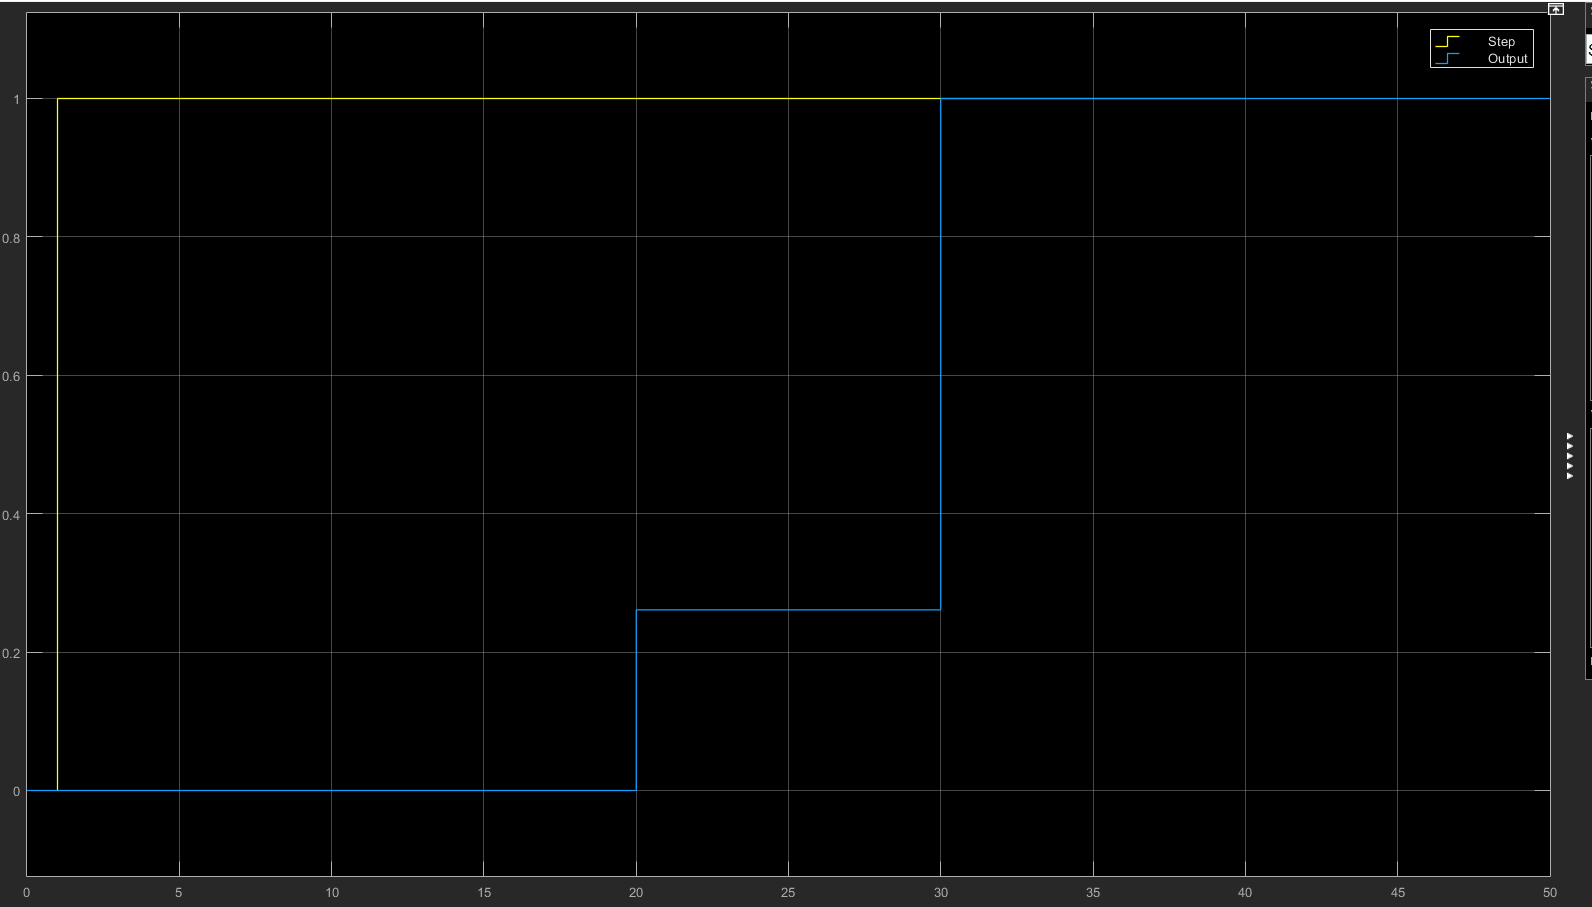

# **Comparing controllers (p8)**

# **State space (p9)**

## Discrete State Space

Ts = 4;
sys = ss(A,B,C,D)


sys =
 
  A = 
             x1        x2        x3
   x1         0      -4.5         0
   x2         0    -0.025   1.3e-05
   x3         0         0  -0.09233
 
  B = 
            u1
   x1        0
   x2        0
   x3  0.08333
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



sys_d = c2d(sys,Ts)


sys_d =
 
  A = 
               x1          x2          x3
   x1           1      -17.13  -0.0004014
   x2           0      0.9048   4.125e-05
   x3           0           0      0.6912
 
  B = 
               u1
   x1  -4.635e-05
   x2   7.434e-06
   x3      0.2787
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Sample time: 4 seconds
Discrete-time state-space model.



G = sys_d.A; H = sys_d.B;

## Controllable & Observable

n = size(G,1);
M = [];
N = [];
for i = 0:n-1
    M = [M G^i*H];
    N = [N ; C*G^i];
end

M

M =    -0.0000   -0.0003   -0.0007
    0.0000    0.0000    0.0000
    0.2787    0.1926    0.1332


fprintf('Rank(M):%i\n',rank(M))

Rank(M):3


if rank(M) == n
    disp('(G,H) is controllable')
end

(G,H) is controllable



N

N =     1.0000         0         0
    1.0000  -17.1293   -0.0004
    1.0000  -32.6285   -0.0014


fprintf('Rank(N):%i\n',rank(N))

Rank(N):3


if rank(N) == n
    disp('(G,C) is observable')
end

(G,C) is observable



% Hankel Matrix
if rank(N*M) == n
    disp('State space is minimal')
end

State space is minimal


# **DeadBeat controller from the state space (p10)**

% we can use all of the states
tf_d = tf(sys_d)


tf_d =
 
  -4.635e-05 z^2 - 0.0001652 z - 3.666e-05
  ----------------------------------------
     z^3 - 2.596 z^2 + 2.221 z - 0.6254
 
Sample time: 4 seconds
Discrete-time transfer function.



[tf_Num,tf_Den] = tfdata(tf_d);
n = size(tf_Den{1},2);
a = zeros(1,n-1);
b = zeros(1,n);
for i = 1:n-1
    a(i) = tf_Den{1}(i+1);
    b(i) = tf_Num{1}(i);
end
W = [];
for i = 0:n-2
    W = [W ; flip(a(1:end-1-i)) 1 zeros(1,i)];
end
T = M*W;
K_deadbeat = -flip(a)*inv(T)

K_deadbeat =    1.0e+05 *

   -0.0403    1.3010    0.0001


In order to achive the states, we need to impelement the system with delay block:

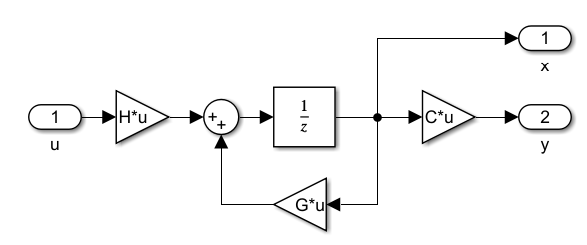

Then simply connect the state feedback controller:

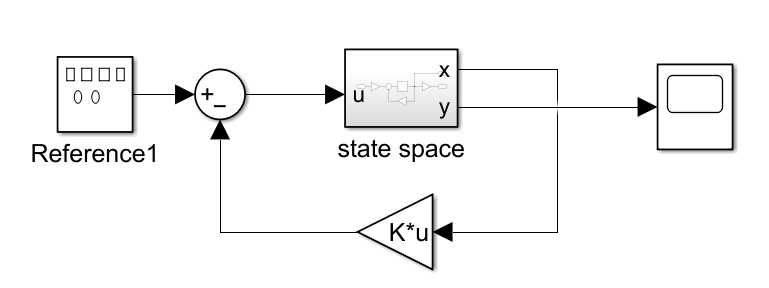

The other way is impelement it as discrete state space block and connect the state feedback controller. But we need to set the C matrix equal to eye(3) because we need all the states in the output:

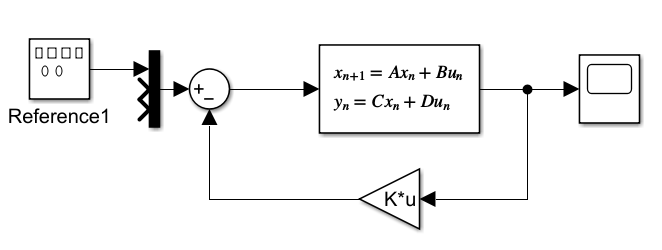

# **Deadbeat controller with full rank observer (p11)**

% x[k+1] = (G-LC)x[k] + Hu[k] + Ly[k]
G_new = transpose(G);
H_new = transpose(C);
L = transpose(acker(G_new,H_new,zeros(n-1,1)))

L =     2.5960
   -0.0997
 -531.9399


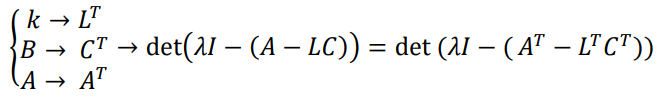

So the block of observer is something like this:

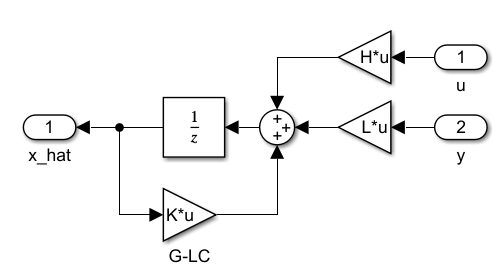

To compare states from system without observer and system with observer we impelement the circuit below.

The input is a sinous signal with the frequencu of 0.005Hz.

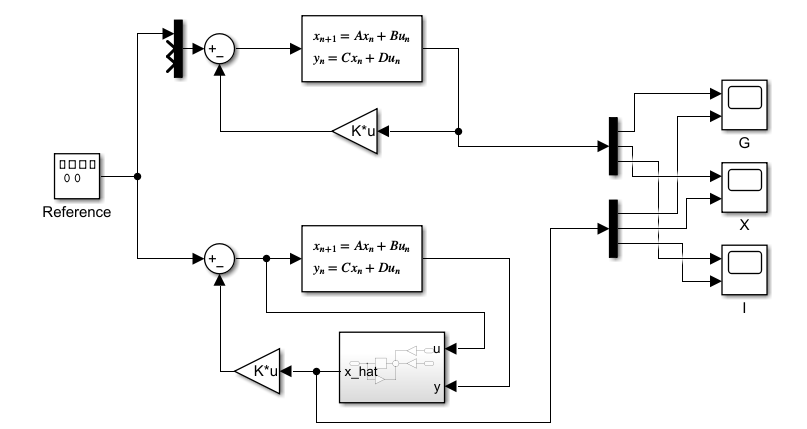

G:

    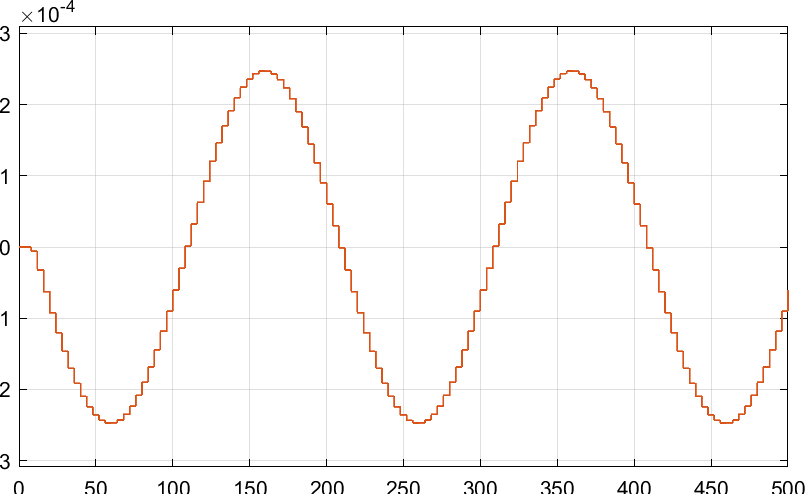

X:

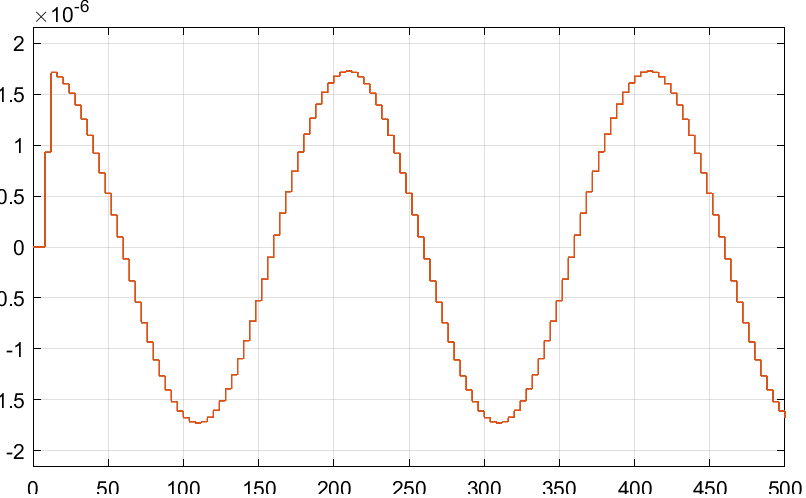

I:

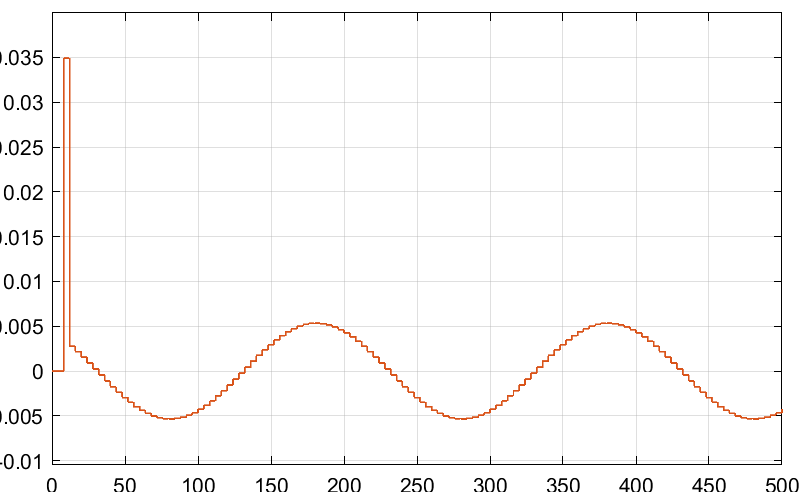

As we can see, observer prefectly follows the states. But if we apply the initial conditions, we can see the error between them that converges to zero over the time.

initial condition = 0.1

G: